# PERFORMANCE COST

Investigates performance of MPC-PD controller with variation in cost.

clear;

%params
tar = 3;

%mpcpd params
pred_horizon = 50;
cont_update = 10;
g = [1; 1; 1; 50; 50; 50];

## cube0

%models
loop_real = 'cube0_mpcpd';
loop_model = 'cube0_mpcpd_model';
sc_real = 'cube0';
sc_model = 'cube0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on');

%params
t_tot = 200;
aux = false;

### b 

1_cube0_b

%info
filename = '1_cube0_b';
info = 'b: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 0.01k^2)';

%params
costfunction = 1;

%mpcpd params
iterations = 25;
learning_rate = 0.1;

%sim and process
simmpcpd;
prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot aux;

### c

1_cube0_c

%info
filename = '1_cube0_c';
info = 'c: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 1e-6w_rw^2 + 0.01k^2)';

%params
costfunction = 2;

%mpcpd params
iterations = 25;
learning_rate = 0.1;

%sim and process
simmpcpd;
prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot aux;

### d

1_cube0_d

%info
filename = '1_cube0_d';
info = 'd: 50 10 [1 1 1 50 50 50] 5 0.2 EG (e^2 + 0.01k^2)';

%params
costfunction = 1;

%mpcpd params
iterations = 5;
learning_rate = 0.5;

%sim and process
simmpcpd;
prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot aux;

## cubewithpanels0

clearvars -except tar pred_horizon cont_update g;

%models
loop_real = 'cubewithpanels0_mpcpd';
loop_model = 'cubewithpanels0_mpcpd_model';
sc_real = 'cubewithpanels0';
sc_model = 'cubewithpanels0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on');

%params
t_tot = 400;
aux = true;

### b

1_cubewithpanels0_b

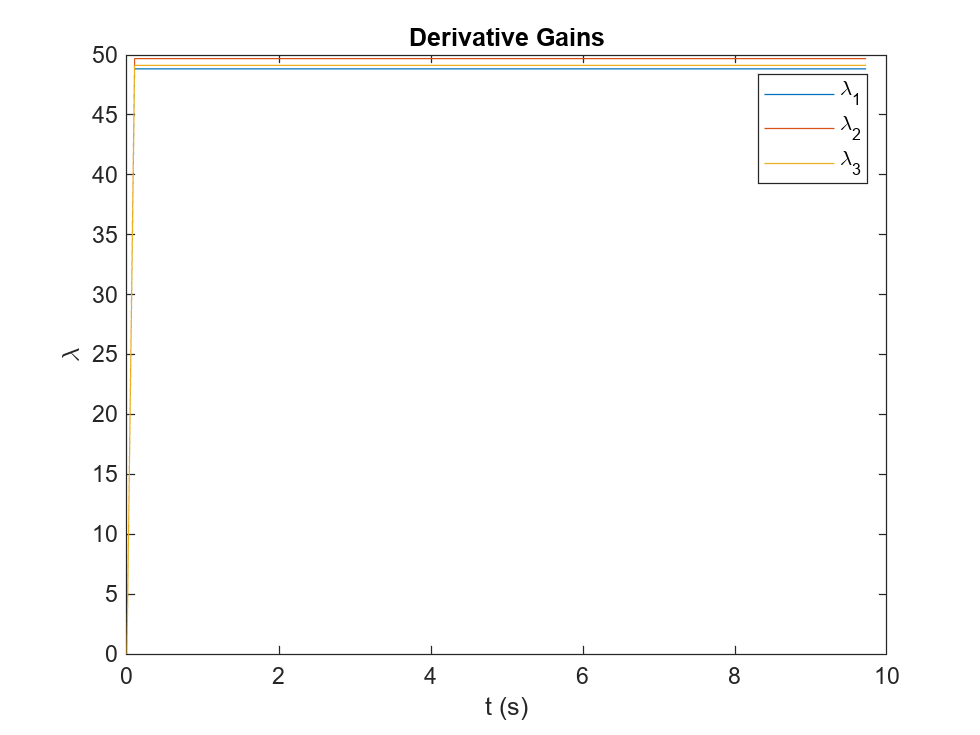

%info
filename = '1_cubewithpanels0_b';
info = 'b: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 0.01k^2)';

%params
costfunction = 1;

%mpcpd params
iterations = 25;
learning_rate = 0.1;

%sim and process
simmpcpd;
prepvisualise;


%clean
close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot aux;

### c

1_cubewithpanels0_c

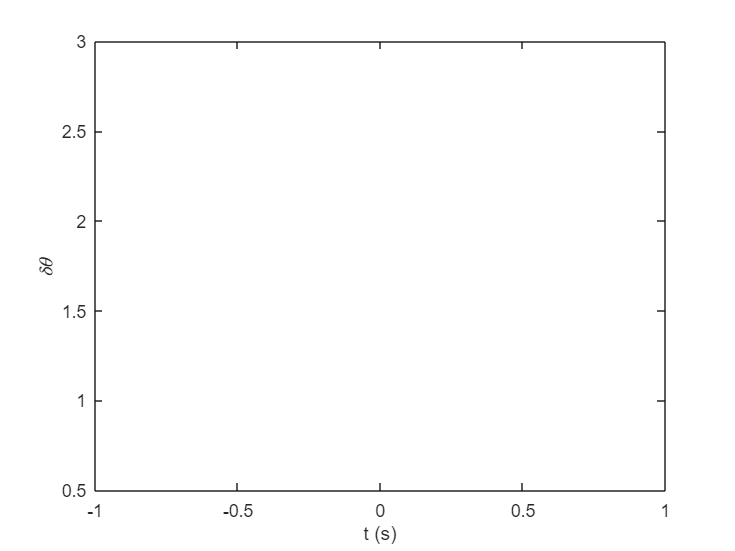

Error using matlab.internal.math.getdimarg
Dimension argument must be a positive integer scalar within indexing range.

Error in cumtrapz>getDimArg (line 91)
    dim = matlab.internal.math.getdimarg(dim);

Error in cumtrapz (line 49)
    dim = min(ndims(y)+1, getDimArg(

%info
filename = '1_cubewithpanels0_c';
info = 'c: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 1e-6w_rw^2 + 0.01k^2)';

%params
costfunction = 2;

%mpcpd params
iterations = 25;
learning_rate = 0.1;

%sim and process
simmpcpd;
prepvisualise;


%clean
close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot aux;

### d

1_cubewithpanels0_d

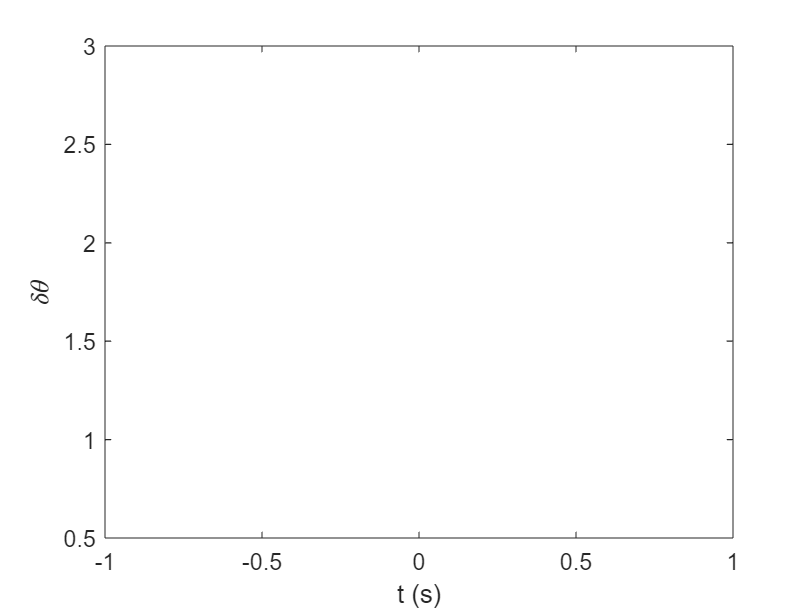

Error using matlab.internal.math.getdimarg
Dimension
argument
must
be a
positive
integer
scalar
within
indexing
range.

Error in cumtrapz>getDimArg (line 91)
    dim = matlab.internal.math.getdimarg(dim);

Error in cumtrapz (line 49)
    dim = min(ndims(y)+1, getDimArg(

%info
filename = '1_cubewithpanels0_d';
info = 'd: 50 10 [1 1 1 50 50 50] 5 0.2 EG (e^2 + 0.01k^2)';

%params
costfunction = 1;

%mpcpd params
iterations = 5;
learning_rate = 0.2;

%sim and process
simmpcpd;
prepvisualise;

%clean

close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot aux;

### e

1_cubewithpanels0_e

%info
filename = '1_cubewithpanels0_e';
info = 'e: 50 10 [1 1 1 50 50 50] 25 0.1 EG (e^2 + 2.5e4theta^2 + 0.01k^2)';

%params
costfunction = 3;

%mpcpd params
iterations = 25;
learning_rate = 0.1;

%sim and process
simmpcpd;
prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g loop_real loop_model sc_real sc_model t_tot aux;